%image=readraw(481,321,'TigerEdge5.raw');
%image=readraw(481,321,'PigEdge5.raw');
%image=readraw(481,321,'TigerCanny-250-300.raw');
%image=readraw(481,321,'PigCanny-250-300.raw');
%image=load('TigerSE.mat');
%image=load('PigSE.mat');
%image=readraw2(481,321,'Tiger gradient.raw');
%image=readraw2(481,321,'Pig gradient.raw');

disp(size(image))

   321   481




% Boundarymap=image;
% disp(Boundarymap)

  1 至 21 列

         0         0    0.0588    0.0510    0.1098    0.1412    0.1529    0.1098    0.0863    0.0314    0.1098    0.0588    0.0353    0.0902    0.1765    0.0353    0.1686    0.2353    0.0353    0.2627    0.2471
         0         0    0.0314    0.0510    0.1216    0.1098    0.1608    0.1020    0.0980    0.0392    0.1020    0.0314    0.0353    0.1059    0.1725    0.0353    0.1569    0.2353    0.0314    0.2627    0.2471
         0         0    0.0314    0.0549    0.1333    0.0980    0.1451    0.1098    0.0980    0.0314    0.0941    0.0275    0.0314    0.1333    0.1725    0.0314    0.1647    0.2392    0.0353    0.2667    0.2471
         0         0    0.0314    0.0471    0.1294    0.0941    0.1333    0.1216    0.1137    0.0275    0.0784    0.0275    0.0314    0.1451    0.1765    0.0314    0.1804    0.2471    0.0275    0.2706    0.2510
         0         0    0.0902    0.0588    0.1176    0.1098    0.1098    0.1137    0.1176    0.0314    0.0706    0.0314    0.0392    0.1451    

Boundarymap=zeros(321,481);
for i = 1 : 321
   for j = 1 : 481
%        if image(i,j)==0
%            Boundarymap(i,j)=1;
%        else
%            Boundarymap(i,j)=0;
%        end
       if image(i,j)==0
           Boundarymap(i,j)=0;
       else
           Boundarymap(i,j)=1;
       end
   end
end
%Boundarymap=image.myimage;
g=load('Tiger_GT.mat')
%g=load('Pig_GT.mat')

g = 包含以下字段的 struct :
    groundTruth: {[1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]  [1×1 struct]}


g=g.groundTruth;

%disp(g{1}.Boundaries)
P=zeros(99)

P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

R=zeros(99)

R =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i=1:5
    groundTruth{1}=g{i};
    %disp(size(Boundarymap))
    %disp(size(groundTruth{1}.Boundaries))
    save('myGT.mat','groundTruth');
    [~, cntR, sumR, cntP, sumP, ~] =edgesEvalImg( Boundarymap,'myGT.mat', {'thrs', 99} )
%      disp([cntP./sumP,i]);
%      disp([cntR./sumR,i]);
    P=P+cntP./sumP
    R=R+cntR./sumR
end

cntR =         1785
        1606
        1774
        1953
        1976
        1999
        1989
        2025
        2033
        2040


sumR =         2069
        2069
        2069
        2069
        2069
        2069
        2069
        2069
        2069
        2069


cntP =         1785
        1606
        1774
        1953
        1976
        1999
        1989
        2025
        2033
        2040


sumP =        25640
       23042
       26325
       31173
       32841
       35283
       36697
       38285
       38951
       39618


P =     0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696    0.0696
    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0.0697    0

R =     0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627    0.8627
    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0.7762    0

cntR =         1923
        1757
        1942
        2126
        2180
        2176
        2160
        2195
        2201
        2208


sumR =         2237
        2237
        2237
        2237
        2237
        2237
        2237
        2237
        2237
        2237


cntP =         1923
        1757
        1942
        2126
        2180
        2176
        2160
        2195
        2201
        2208


sumP =        25640
       23042
       26325
       31173
       32841
       35283
       36697
       38285
       38951
       39618


P =     0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446    0.1446
    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0.1460    0

R =     1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224    1.7224
    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1.5616    1

cntR =         2775
        2826
        3056
        3374
        3429
        3452
        3433
        3465
        3494
        3489


sumR =         3582
        3582
        3582
        3582
        3582
        3582
        3582
        3582
        3582
        3582


cntP =         2775
        2826
        3056
        3374
        3429
        3452
        3433
        3465
        3494
        3489


sumP =        25640
       23042
       26325
       31173
       32841
       35283
       36697
       38285
       38951
       39618


P =     0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528    0.2528
    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0.2686    0

R =     2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971    2.4971
    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2.3506    2

cntR =         3219
        3482
        3828
        4199
        4254
        4295
        4289
        4296
        4331
        4337


sumR =         4502
        4502
        4502
        4502
        4502
        4502
        4502
        4502
        4502
        4502


cntP =         3219
        3482
        3828
        4199
        4254
        4295
        4289
        4296
        4331
        4337


sumP =        25640
       23042
       26325
       31173
       32841
       35283
       36697
       38285
       38951
       39618


P =     0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784    0.3784
    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0.4197    0

R =     3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121    3.2121
    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3.1240    3

cntR =         2616
        2709
        2960
        3266
        3340
        3366
        3353
        3393
        3419
        3418


sumR =         3497
        3497
        3497
        3497
        3497
        3497
        3497
        3497
        3497
        3497


cntP =         2616
        2709
        2960
        3266
        3340
        3366
        3353
        3393
        3419
        3418


sumP =        25640
       23042
       26325
       31173
       32841
       35283
       36697
       38285
       38951
       39618


P =     0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804    0.4804
    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0.5373    0

R =     3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602    3.9602
    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3.8987    3

P=P/5

P =     0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961    0.0961
    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0.1075    0

R=R/5

R =     0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920    0.7920
    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0.7797    0

F=2.*P.*R./(P+R)

F =     0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714    0.1714
    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0.1889    0


x=linspace(0.01,0.99,99)

x =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


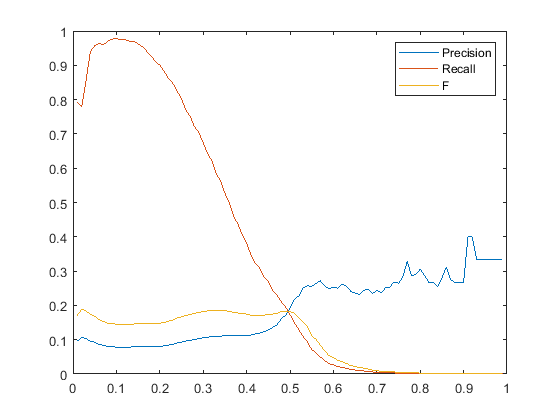


plot(x,P);hold on;
plot(x,R);hold on;
plot(x,F);hold on;
legend('Precision','Recall','F')